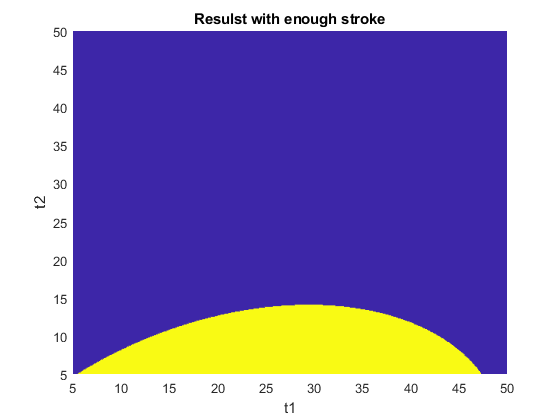

margin = 1E-3; %margin space between actuator and beam [m]
d = 40E-3; %thickness beams part [m]
w_a = 10E-3; %width actuator [m]

h_tot = 100E-3;
L_A = 80E-3;
b = 0;

t1_0 = 5; %mm
t1_1 = 50; %mm
t1_step = 0.1;
t1 = [t1_0:t1_step:t1_1]*1E-3; %m
Lt1 = length(t1);

t2_0 = 5; %mm
t2_1 = 50; %mm
t2_step = 0.1;
t2 = [t2_0:t1_step:t2_1]*1E-3; %m
Lt2 = length(t2);



Ctot = zeros(Lt1,Lt2);
tr = zeros(Lt1,Lt2);
m = zeros(Lt1,Lt2);
Isvalid = zeros(Lt1,Lt2);
Isgood = zeros(Lt1,Lt2);
S_out = zeros(Lt1,Lt2);
        
for i=1:Lt1
    for j=1:Lt2
        pbeam = parralelbeam(t1(i),t2(j),b,L_A,h_tot,margin,d,w_a);
        pbeam = pbeam.compdimension1();
        pbeam = pbeam.calc();
        pbeam = pbeam.testvalid();
        Ctot(i,j) = pbeam.Ctot;
        tr(i,j) = pbeam.i;
        m(i,j) = pbeam.m;
        Isvalid(i,j) = pbeam.isvalid;
        Isgood(i,j) = pbeam.isGood;
        S_out(i,j) = pbeam.S_out;
    end
end

[X,Y] = meshgrid(t1_0:t1_step:t1_1,t2_0:t2_step:t2_1);
labelx = "t1";
labely = "t2";

figure 
clf
hold on
s1 = surf(Y,X,Isgood);
s1.EdgeColor = 'none';

title('Resulst with enough stroke')
xlabel(labelx)
ylabel(labely)

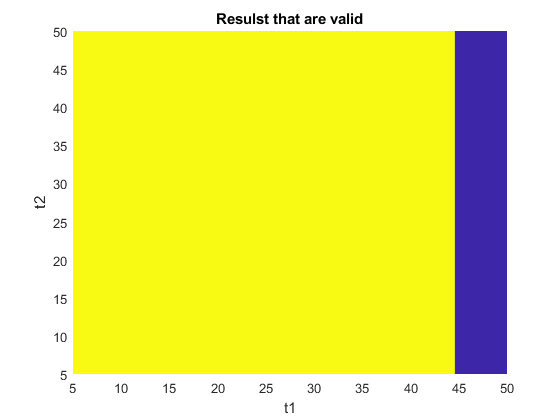

figure 
clf
hold on
s1 = surf(Y,X,Isvalid);
s1.EdgeColor = 'none';

title('Resulst that are valid')
xlabel(labelx)
ylabel(labely)

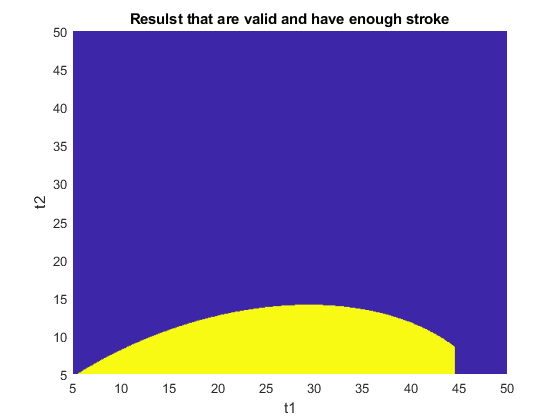

validmap = Isvalid.*Isgood;
figure 
clf
hold on
s1 = surf(Y,X,validmap);
s1.EdgeColor = 'none';

title('Resulst that are valid and have enough stroke')
xlabel(labelx)
ylabel(labely)

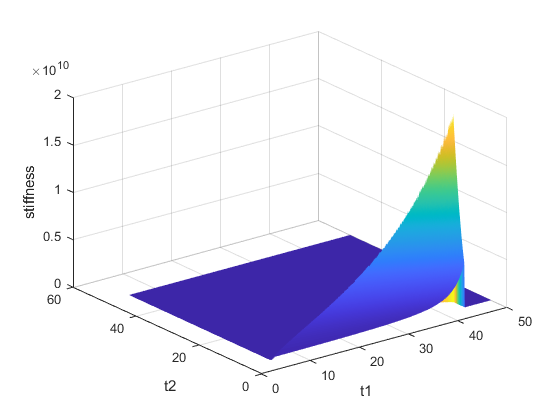

figure 
clf
s1 = surf(Y,X,Ctot.*validmap);
s1.EdgeColor = 'none';

xlabel(labelx)
ylabel(labely)
zlabel('stiffness')

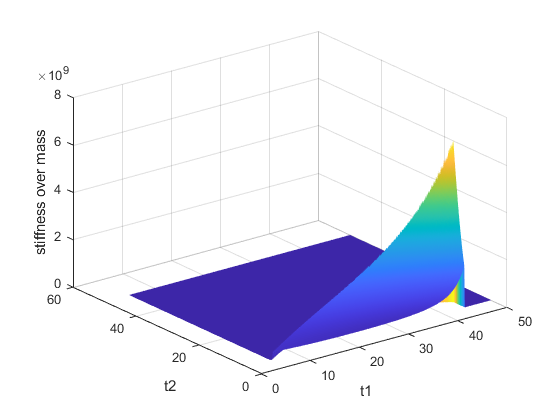


figure 
clf
s1 = surf(Y,X,Ctot.*validmap./m);
s1.EdgeColor = 'none';

xlabel(labelx)
ylabel(labely)
zlabel('stiffness over mass')

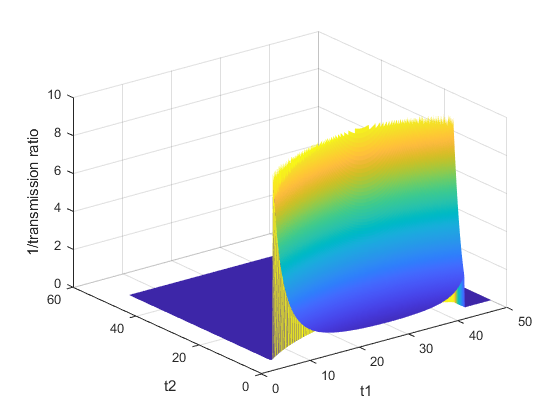


figure 
clf
s1 = surf(Y,X,validmap./tr);
s1.EdgeColor = 'none';

xlabel(labelx)
ylabel(labely)
zlabel('1/transmission ratio')

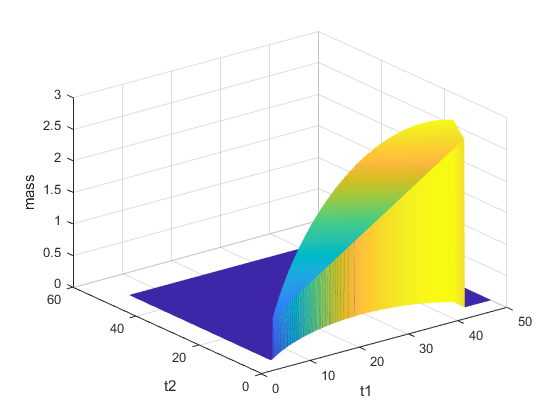


figure 
clf
s1 = surf(Y,X,m.*validmap);
s1.EdgeColor = 'none';

xlabel(labelx)
ylabel(labely)
zlabel('mass')

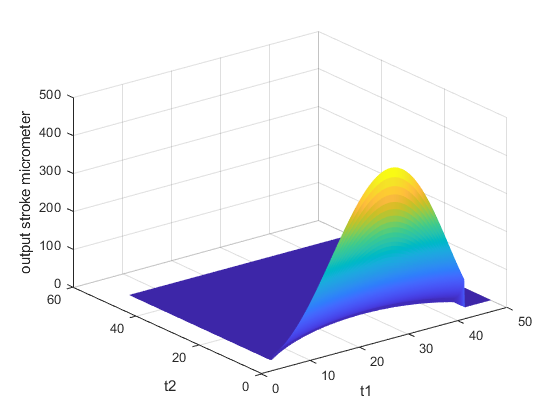


figure 
clf
s1 = surf(Y,X,S_out.*validmap);
s1.EdgeColor = 'none';

xlabel(labelx)
ylabel(labely)
zlabel('output stroke micrometer')